# Full 3D Simulation of CoM Estimation Strategy

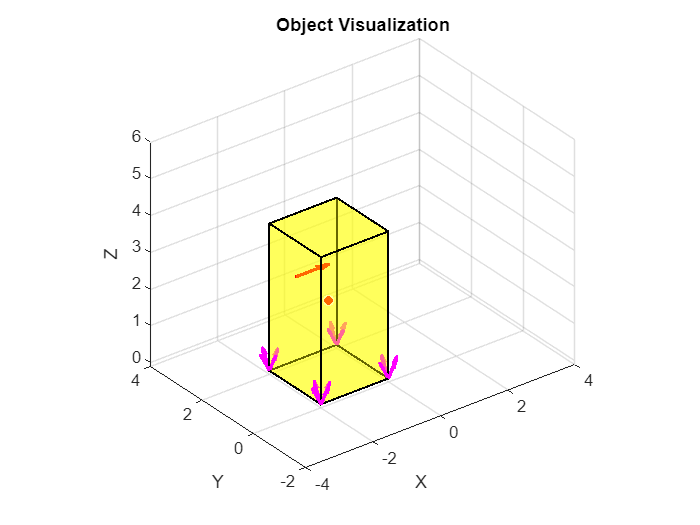

clc; clear; close all;
addpath("Utilities\");

% First set the problem and object parameters (FOR NOW A RECTANGULAR BOX)
mass    = 1;
fric    = 0.5;
width   = 2;
height  = 4;
origin  = [0; 0; 0]; % ORIGIN (for simplicity, this is at tipping edge on smallest y (into page) vertex)
com     = [-width/2; width/2; height/2]; % com defined from origin
hf      = 3;         % Height above the table where f applied
Pf      = [-width; 1; hf]; % point of external force applied
Fp      = [1; 0; 0]; % magnitude of linear force applied

viewf   = [0 -1 0]; % Front view (-y towards camera)
viewt   = [0 0 1];  % Top view (z towards camera)


body = body('mass',mass, 'mu',fric, 'com',com, 'width',width, ...
    'height',height, 'Pf',Pf, 'Fp',Fp, 'origin',[-width;0;0]);


% Now visualize the object

% 3D view
body.plot(gca); hold off; figure;

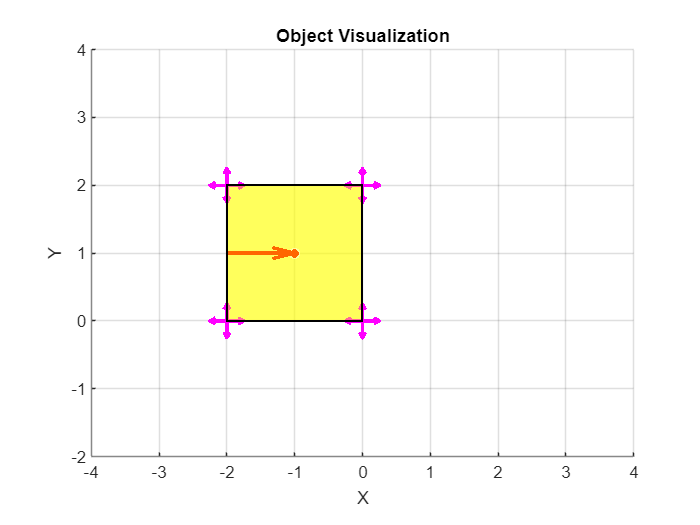

% Top view (xy)
body.plot(gca, viewt); hold off; figure;

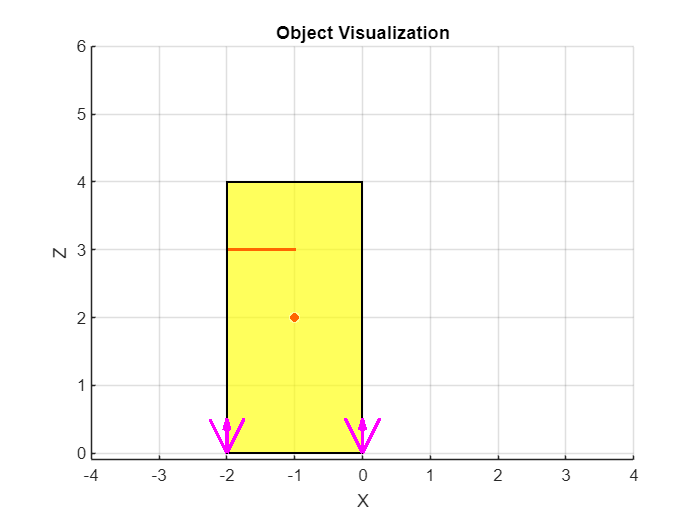

% Front view (xz)
body.plot(gca, viewf); hold off; figure;

## First, scalar analysis of the SLIDING/TIPPING condition

% Scalar being the basic sliding/tipping thresholds

syms mu m g r_w h_c d positive
syms F_p h_f real

% Incipient SLIDING is when F(push) >= f(fric). recall that {ft <= mu*f(normal)}. x-axis equilibrium.
slide_F = solve( F_p == mu*m*g, F_p );

% Incipient TIPPING is when M(push) > M(gravity). recall that {M = f*r}. y-axis moment equilibrium.
% (also recall at incipient tip, norm and fric generate no moment since they occur @ tipping point
tip_F   = solve( F_p*h_f == m*g*r_w, F_p );

% tip_cond_F = solve(subs(tip_eqn, [m g r_w h_f], [mass 9.8 -body.com(1) hf]), F_p) % r_w from com to tip edge
% should probably generalize ^this^ to check for the furthest point from the push side, but not for now

slide_val = double( subs(slide_F, [mu,m,g], [fric,mass,9.8]) );
tip_val   = double( subs(tip_F,   [m,g,r_w,h_f], [mass,9.8,abs(body.com(1)),hf]) );



% Print Conditionals
cond = 'SLIDING and TIPPING';
if isAlways(slide_val < tip_val); cond = char('SLIDING'); end
if isAlways(tip_val < slide_val); cond = char('TIPPING'); end
fprintf('F required for sliding: %.3f and tipping: %.3f', slide_val, tip_val)

F required for sliding: 4.900 and tipping: 3.267

fprintf('\n%s will occur because its the smaller of the two by: %.3f.\n', cond, abs(round(slide_val - tip_val, 3)))

TIPPING will occur because its the smaller of the two by: 1.633.




% For fun, find height where sliding and tipping occurs simultaneously, given current object geometry
ts_eqn = solve(m*g*r_w/(h_f) == mu*m*g, h_f);
ts_val = double( subs(ts_eqn, [r_w mu], [-com(1) fric]) );
fprintf('h_f required for current geometry and friction: %.3f', ts_val)

h_f required for current geometry and friction: 2.000

## Next, scalar analysis of TOPPLING condition

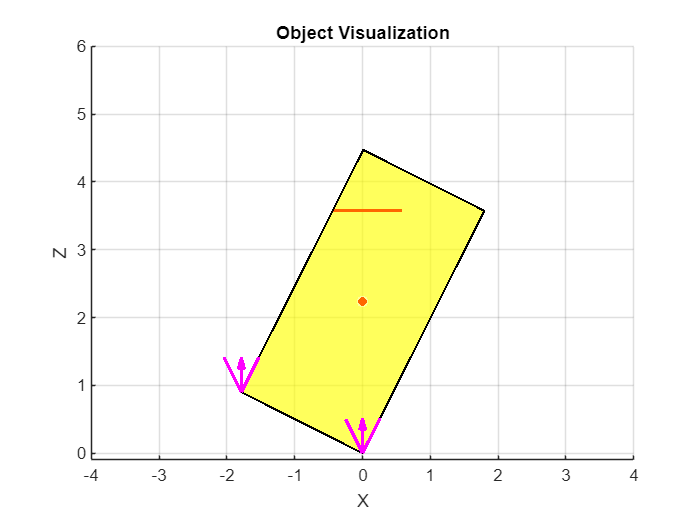

% A finger located at Pf (relative to object frame) continually pushes with force Fp until object comes to
% unstable equilibrium (ZMP: zero moment point). At any time t during motion, static equilibrium is present

% Assume TIPPING condition is active i.e. F(t=0) = F_tip
F = tip_val;
angle_step = -0.1; % degrees. 'step' for each object/plotting update. Can be arbitrarily small.
flist = [];
angles = [];

current_angle = 0;

% Lets 'simulate' bringing object to toppling threshold. No physics, just visual + geometry analysis.
while F > 0
    angles(end+1,1) = current_angle;
    flist(end+1,1) = F; % (this is the force required to maintain equilibrium at current time)

    % The force required for equilibrium drops bc rw drops AND hf increases
    rw_i = -body.com(1);    % x-distance from CoM to tip edge
    hf_i = body.Pf(3);      % z-distance (height) of push from tip edge
    % Moment equation at this time
    F = (9.8*mass*rw_i)/hf_i;

    T = [R3(angle_step, [0;-1;0],'deg') [0;0;0]; 0 0 0 1];
    body.move(T)
    % body.plot(gca, viewf) % Uncomment to plot in the loop (CAUTION: THIS MAY CRASH MATLAB)

    current_angle = current_angle + angle_step;
end
angles_mag = abs(angles);

% Visualize the object and the Force graph
body.plot(gca, viewf);

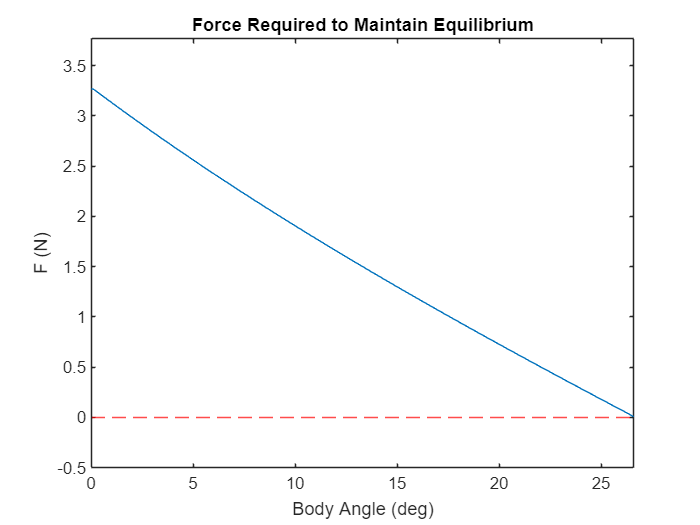

figure; plot(angles_mag, flist); hold on; yline(0,'--r');
xlim([0, angles_mag(end)]); ylim([-0.5 tip_val+0.5]); xlabel('Body Angle (deg)'); ylabel('F (N)')
title('Force Required to Maintain Equilibrium'); hold off;


% Now we know the final angle of the payload at which toppling occurs.
topple_final_angle = angles(end);
fprintf('\nToppling occurs at object angle %.2f deg.', topple_final_angle)


Toppling occurs at object angle -26.60 deg.

% Let's reset the object for the next section
reset_angle = -topple_final_angle;
T = [R3(reset_angle, [0;-1;0],'deg') [0;0;0]; 0 0 0 1];
body.move(T);

## Now, let's try approximating the force curve with a small push

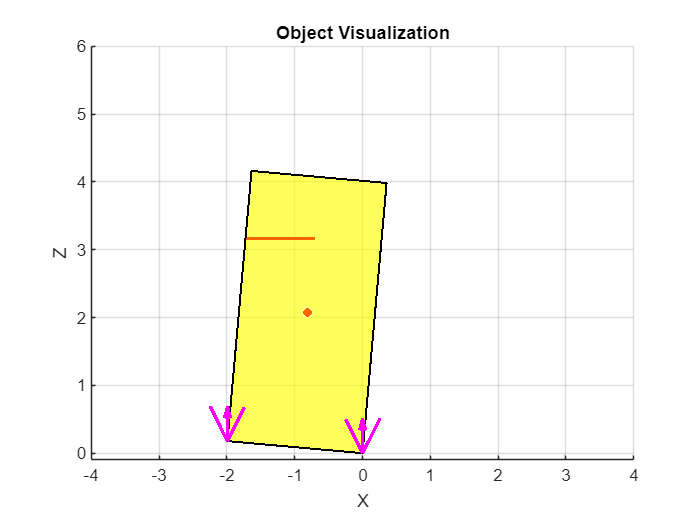

F_approx = tip_val;
final_angle = -5;   % degrees. 'final' angle - bring object to this angle and no further
angle_step = -0.1;  % again, arbitrary. akin to time step.
angles = [];
flist = [];

prev_angle = 0;
% current_angle = 0;

for j = 0 : angle_step : final_angle
    angles(end+1,1) = j;
    flist(end+1,1) = F_approx; % (this is the force required to maintain equilibrium at current time)

    % The force required for equilibrium drops because rw drops AND hf increases
    rw_i = -(body.com(1));
    hf_i = body.Pf(3);
    % Moment equation at this time
    F_approx = (9.8*mass*rw_i)/hf_i;
    
    dTheta = j - prev_angle;
    T = [R3(dTheta, [0;-1;0],'deg') [0;0;0]; 0 0 0 1];
    body.move(T);
    % body.plot(gca, viewf) % Uncomment to plot in the loop (CAUTION: THIS MAY CRASH MATLAB)
    prev_angle = j;
end

% For visualization, make topple angles positive
angles_mag = abs(angles);

% Visualize the object and the Force graph
close all;
body.plot(gca, viewf);

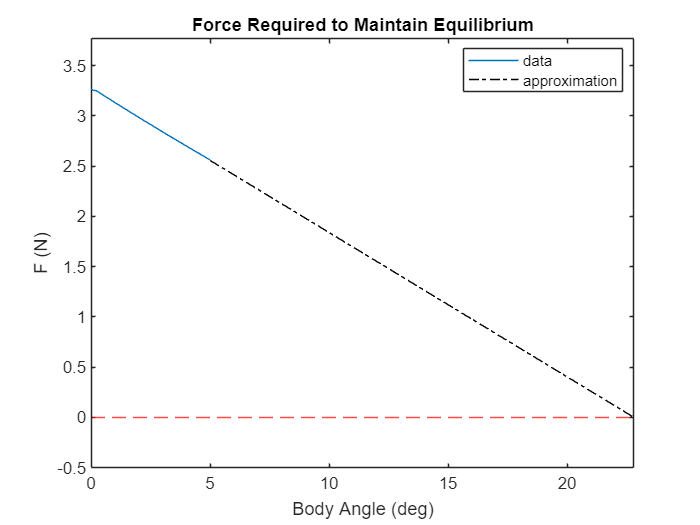

figure; datapoints = plot(angles_mag, flist); hold on; yline(0,'--r');
xlim([0, angles_mag(end)]); ylim([-0.5 tip_val+0.5]); xlabel('Body Angle (deg)'); ylabel('F (N)')
title('Force Required to Maintain Equilibrium'); hold on;

% Now let's approximate the force curve given the data subset
n = 1; % Linear approximation
p = polyfit(angles_mag, flist, n);
r = roots(p);
topple_angle_approx = r( imag(r)==0 ); % Save only the real roots

% Visualize the approximation
xx = linspace(abs(final_angle), topple_angle_approx, 20);
yy = polyval(p, xx);
approx = plot(xx, yy, 'k-.'); xlim([0, topple_angle_approx]); ylim([-0.5 tip_val+0.5]);
legend([datapoints, approx],'data','approximation', 'Location','best');


% Now we know APPROXIMATELY angle at which toppling occurs.
fprintf(['\nToppling occurs at approximately %.2f deg. We know the CoM is\n' ...
    'on the plane that is this angle from the plane of travel.'], sign(final_angle)*topple_angle_approx)


Toppling occurs at approximately -22.80 deg. We know the CoM is
on the plane that is this angle from the plane of travel.

% Let's reset the object for the next section
reset_angle = -angles(end);
T = [R3(reset_angle, [0;-1;0],'deg') [0;0;0]; 0 0 0 1];
body.move(T);

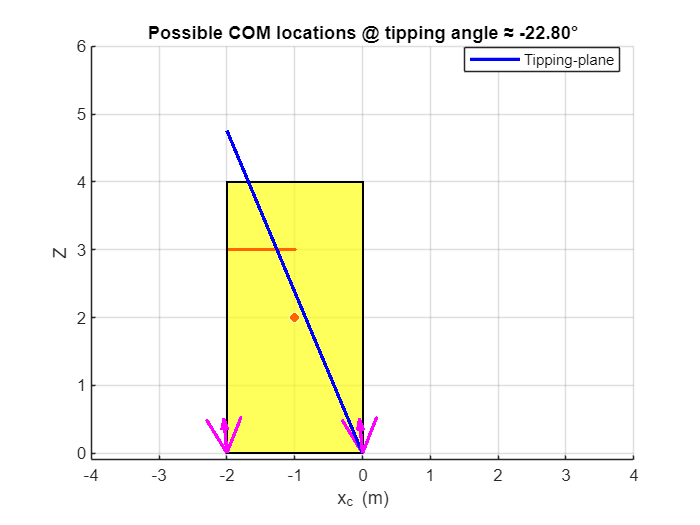

% Finally, let's try to calculate the CoM possibilities using this:

% Use the approximate tipping angle you found:
theta_app = sign(final_angle) * topple_angle_approx;    % in degrees
theta_rad = deg2rad(theta_app);                         % convert to radians

% Solve for z_c in terms of x_c on the tipping plane:
syms xc zc real
% zc_plane = solve( xc*cos(theta_rad) + zc*sin(theta_rad) == 0, zc );
zc_plane = solve( zc == xc/tan(theta_rad), zc );

% Sample across the object width:
xc_vals = linspace(-width, 0, 50);              % plausible x_c range
yc_vals = zeros([1, length(xc_vals)]);                  % y_c = 0
zc_vals = double( subs(zc_plane, xc, xc_vals) );        % corresponding z_c

figure;
body.plot(gca, viewf);
hold on;
% Plot the result
poss_com_vals = plot3(xc_vals, yc_vals, zc_vals, 'b-', 'LineWidth', 2);
% also mark your current COM for reference
xlabel('x_c (m)');
ylabel('z_c (m)');
title(sprintf('Possible COM locations @ tipping angle ≈ %.2f°', theta_app));
legend(poss_com_vals,'Tipping‐plane','Location','best');
grid on;

## Given this, we can now either:

- Use our 2D CoM to approximate the 3D CoM

- Push from a different side to get two planes, then find their intersection

Possible (complete!) Procedure:

- Analyze object to determine optimal pushing side opposite flat edge.

- Trial a push somewhere along its height, starting in the middle of the object.

- If not tipping, move upwards until beyond/above tipping threshold.

- Now push for a bit towards toppling point and collect F/T data 

- Calculate plane in which vertical CoM lies within.

- Perform option 1 or 2 from above to get 3D CoM.